#### Script para calcular x, be, e, sign y f a partir de una cadena de caracteres en hexa. 

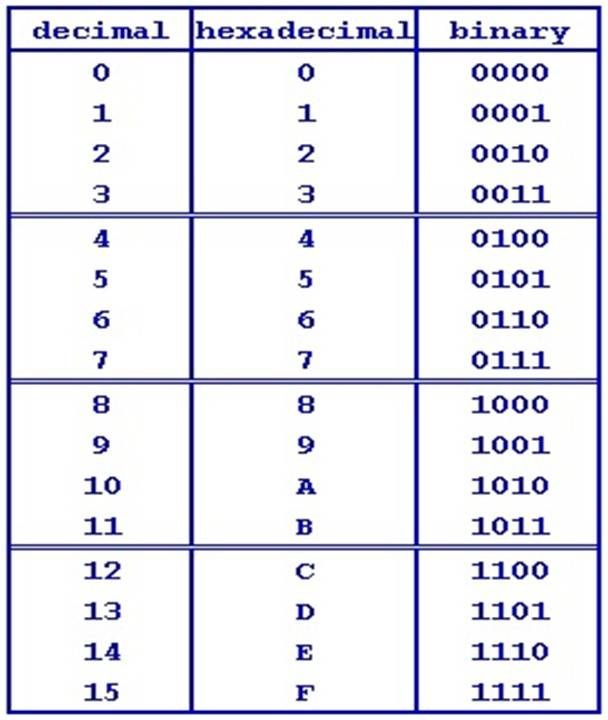

Para el signo solo nos preocupamos si es >=8;

%format hex
%repHex = num2hex(num) 
hexNum = '0123456789abcdef';
%sign es el primer bit del binario del primer caracter. 
% En este caso 0 -> 0000 y el bit mas significativo= 0.
%Si el primer bit es 0 => el numero es positivo (1)
%Si el primer bit es 1 => el numero es negativo (-1)
signo=1;

%Los primeros 3 caracteres sin contar el bit del signo 
beV= [0 1 2]

beV =      0     1     2


aux = [2 1 0]

aux =      2     1     0


be=sum(beV.*16.^aux)

be = 18

exp= be-1023;

fVec = [3 4 5 6 7 8 9 10 11 12 13 14 15]; 
i = 1:13; %Index de sus respectivas posiciones
f = sum(fVec./(16.^i)) %Hago la suma de tal modo que sea un agregado del valor en decimal de cada dígito hexadecimal

f = 0.2044

x = signo*(1 + fVec) * 2^exp;

x = 	1.0e+-301 *

    0.1167    0.1458    0.1750    0.2042    0.2333    0.2625    0.2916    0.3208    0.3500    0.3791    0.4083    0.4375    0.4666



disp(x);

  1.0e-301 *

    0.1167    0.1458    0.1750    0.2042    0.2333    0.2625    0.2916    0.3208    0.3500    0.3791    0.4083    0.4375    0.4666

